%Exercise 1.1 Spectral sensitivity functions
% Figure for Ad

load('Ad.mat');
load('Ad2.mat');

disp('Exercise 1.1');

Exercise 1.1


disp('Spectral sensitivity functions')

Spectral sensitivity functions


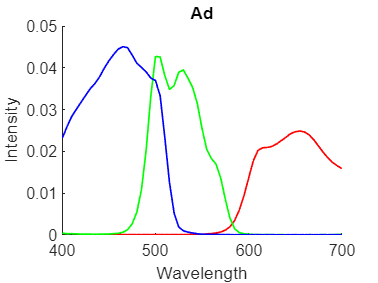

figure;
%plot(Ad);


%Values from 400 to 700
x = linspace(400, 700, size(Ad, 1));
title('Ad');
xlabel('Wavelength');
ylabel('Intensity');

%Print the curves for R,G,B
hold on
plot(x, Ad(:, 1), 'r', 'LineWidth', 1); % R - column 1
plot(x, Ad(:, 2), 'g', 'LineWidth', 1); % G - column 2
plot(x, Ad(:, 3), 'b', 'LineWidth', 1); % B - column 3
hold off

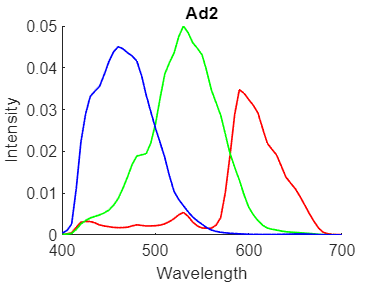



%Create new window for Ad2
figure;
x = linspace(400, 700, size(Ad2, 1)); % Skapa x-axelvärden från 400 till 700
title('Ad2');
xlabel('Wavelength');
ylabel('Intensity');

%Print the curves for R,G,B
hold on
plot(x, Ad2(:, 1), 'r', 'LineWidth', 1); % R - column 1
plot(x, Ad2(:, 2), 'g', 'LineWidth', 1); % G - column 2
plot(x, Ad2(:, 3), 'b', 'LineWidth', 1); % B - column 3
hold off

%Exercise 1.2 Un-calibrated RGB-signals
%Equation 7: d = Ad^t*e^t (^t equals transpose matrix)
%CIED65 represents daylight
%e -> input spectral radiance (chips20(:,:).*CIED65)
%Compute d for Ad
load('chips20.mat');

disp('Exercise 1.2');

Exercise 1.2


disp('Un-calibrated RGB-signals')

Un-calibrated RGB-signals


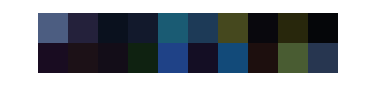


RGB_raw_D65 = Ad'*(chips20(:,:).*CIED65)';
RGB2_raw_D65 = Ad2'*(chips20(:,:).*CIED65)';

%Uncalibrated, device dependent camera outputs:
showRGB(RGB_raw_D65');


%Save as png
%saveas(gcf, 'RGB_raw_D65.png');

showRGB(RGB_raw_D65');

%Exercise 2.1 Calibrated RGB-signals, normalize factors
%Equation 7: d = Ad^t*e^t (^t equals transpose matrix)

disp('Exercise 2.1 Calibrated RGB-signals');

Exercise 2.1 Calibrated RGB-signals


disp('Normalization factors')

Normalization factors


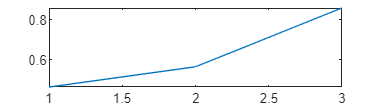


%White input spectrum
e = ones(1,61);

%Normalization factors so R'=G'=B'=1 for white input spectrum
norm_Ad = Ad'*e';
norm_Ad2 = Ad2'*e';



plot(norm_Ad);

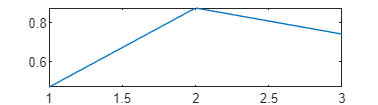

plot(norm_Ad2);

%Exercise 2.2 Calibrated RGB-signals 
%Compensate for sensor characteristics

disp('Exercise 2.2 Calibrated RGB-signals');

Exercise 2.2 Calibrated RGB-signals


disp('Compensate for sensor characteristics')

Compensate for sensor characteristics


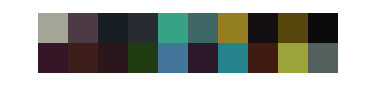


RGB_cal_D65 = (Ad'*(chips20(:,:).*CIED65)')./norm_Ad;
RGB2_cal_D65 = (Ad2'*(chips20(:,:).*CIED65)')./norm_Ad2;

showRGB(RGB_cal_D65');

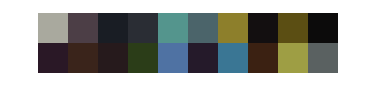


%Save as png
%saveas(gcf, 'RGB_cal_D65.png');

showRGB(RGB2_cal_D65');

%Exercise 2.3 Calibrated RBG-signals, different lightsource
%CIEA -> represent indoor light

disp('Exercise 2.3 Calibrated RGB-signals');

Exercise 2.3 Calibrated RGB-signals


disp('Different lightsources')

Different lightsources


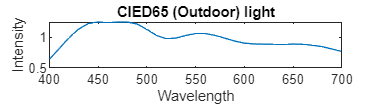


%Wavelengths
x = 400:5:700;

% Plot
plot(x, CIED65);
xlabel('Wavelength');  
ylabel('Intensity');  
title('CIED65 (Outdoor) light');

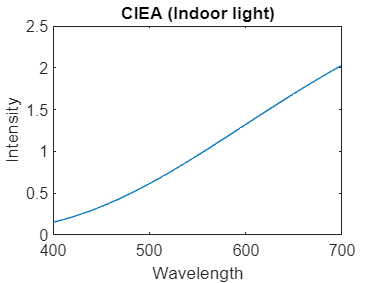


figure;
% Plot
plot(x, CIEA);
xlabel('Wavelength');  
ylabel('Intensity');  
title('CIEA (Indoor light)');

%Exercise 2.4 Calibrated RBG-signals

disp('Exercise 2.4 Calibrated RGB-signals');

Exercise 2.4 Calibrated RGB-signals


disp('Camera 1 under illuminant CIEA and CIED65')

Camera 1 under illuminant CIEA and CIED65



RGB_CIEA = (Ad'*(chips20(:,:).*CIEA)')./norm_Ad;
RGB_CIED652 = (Ad'*(chips20(:,:).*CIED65)')./norm_Ad;

showRGB(RGB_CIED652');

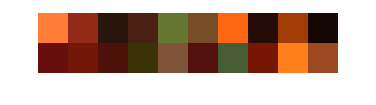

showRGB(RGB_CIEA');

%Exercise 2.5 Calibrated RBG-signals
%Equation 8: d = Ad'*(chips20(10,:).*CIEA)'
%Use R instead of chips

disp('Exercise 2.5 Calibrated RGB-signals');

Exercise 2.5 Calibrated RGB-signals


disp('New normalization factors based on illumination')

New normalization factors based on illumination


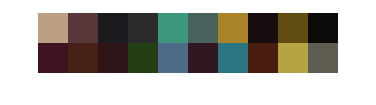


%White input spectrum
R = ones(1,61);

%New normalization factors, using Equation 8
%Based on specific illumination
norm_D65 = (Ad'*(R.*CIED65)');
norm_A = (Ad'*(R.*CIEA)');

%Normalize
RGB_cal_A = (Ad'*(chips20(:,:).*CIEA)')./norm_A;
RGB_cal_D652 = (Ad'*(chips20(:,:).*CIED65)')./norm_D65;


showRGB(RGB_cal_A');

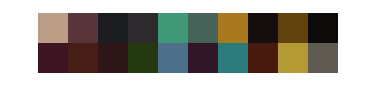

showRGB(RGB_cal_D652');

%Exercise 3.1 Calculate XYZ-values
disp('Exercise 3.1 ');

Exercise 3.1 


disp('Computing XYZ-values');

Computing XYZ-values



%Equation 7: d = A^t*e^t

%Normalization factor
k = 100./(CIED65*xyz(:,2));

%XYZ-values 
XYZ_D65_ref = xyz'*( chips20(:,:).*CIED65)' .* k;

%Gives y = 100 if reflectance is white
XYZ = k *xyz'*(R.*CIED65)';

%XYZ_D65 = xyz2lab(chips20(:,:)', CIED65');

%Exercise 3.2
load('M_XYZ2RGB.mat');

disp('Exercise 3.2 ');

Exercise 3.2 


disp('Color difference values');

Color difference values



%XYZ values for the calibrated RGB
MXYZ_inv = inv(M_XYZ2RGB)*RGB_cal_D65;

%Estimation values in CIELAB
[L, a, b] =  xyz2lab(MXYZ_inv(1,:)', MXYZ_inv(2,:)', MXYZ_inv(3,:)');


E_LAB = zeros(3,20);
E_LAB(1,:) = L;
E_LAB(2,:) = a;
E_LAB(3,:) = b;

%Reference
[L, a, b] =  xyz2lab(XYZ_D65_ref(1,:)', XYZ_D65_ref(2,:)', XYZ_D65_ref(3,:)');

REF_LAB = zeros(3,20);
REF_LAB(1,:) = L;
REF_LAB(2,:) = a;
REF_LAB(3,:) = b;
    
%Color difference
dE = sqrt((E_LAB(1,:)-REF_LAB(1,:)).^2+(E_LAB(2,:)-REF_LAB(2,:)).^2+(E_LAB(3,:)-REF_LAB(3,:)).^2);

dE_Mean = mean(dE)

dE_Mean = 12.6418

dE_Max = max(dE)

dE_Max = 31.6232

%Exercise 3.3
disp('Exercise 3.3 ');

Exercise 3.3 


disp('Plot Ad (Camera) och CMF ');

Plot Ad (Camera) och CMF 


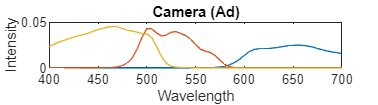


x = 400:5:700;
plot(x,Ad);
xlabel('Wavelength');  
ylabel('Intensity'); 
title('Camera (Ad)');

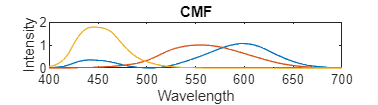


plot(x,xyz);
xlabel('Wavelength');  
ylabel('Intensity'); 
title('CMF');

%Exercise 3.4
disp('Exercise 3.4 ');

Exercise 3.4 


disp('Calculate color difference using lineaer regression');

Calculate color difference using lineaer regression


%Calculate A with linear regression

%Conversion-matrix between RGB to XYZ for the specific samples and device
A = pinv(RGB_cal_D65') * XYZ_D65_ref';

%Estimation matrix from conversion
estimate = RGB_cal_D65'*A;

%For use in lab2
save('XYZ_D65_ref.mat', 'XYZ_D65_ref');

%Calculate the color difference
dE2 = ColorDiff(XYZ_D65_ref, estimate');

%Mean and maximum value of the color difference
dE_Mean2 = mean(dE2)

dE_Mean2 = 2.1977

dE_Max2 = max(dE2)

dE_Max2 = 5.8376

%Exercise 3.5
disp('Exercise 3.5 ');

Exercise 3.5 


disp('Calculate color difference using polynomial regression');

Calculate color difference using polynomial regression



%Calculate a with polynomial regression
A = Optimize_poly(RGB_cal_D65, XYZ_D65_ref);

%Estimation matrix from conversion
estimate = Polynomial_regression(RGB_cal_D65, A);

%For use in lab2
save('estimate.mat', 'estimate');

%Calculate the color difference
e = ColorDiff(XYZ_D65_ref, estimate);

%Mean and maximum value of the color difference
dE_Mean3 = mean(e)

dE_Mean3 = 1.0238

dE_Mean3 = max(e)

dE_Mean3 = 3.1053